%% 1. DATA SETUP: Generate "Two Moons" Data
% MATLAB doesn't have 'make_moons', so we generate it mathematically.
clear; clc; close all;

n_samples = 500; % Reduced from 2000 for efficiency
sigma_noise = sqrt(0.02);

% Create two half-circles
n1 = floor(n_samples / 2);
n2 = n_samples - n1;

theta1 = linspace(0, pi, n1)';
theta2 = linspace(0, pi, n2)';

% Moon 1 (Upper)
x1 = [cos(theta1), sin(theta1)];
% Moon 2 (Lower) - shifted and flipped
x2 = [1 - cos(theta2), 1 - sin(theta2) - 0.5];

% Combine and add noise
X = [x1; x2];
X = X + sigma_noise * randn(size(X));

% Labels (for checking truth later)
y = [ones(n1, 1); 2 * ones(n2, 1)];

%% 2. GRAPH CONSTRUCTION
disp('Building Graph...');

Building Graph...



% Calculate full pairwise Euclidean Distance Matrix
% Using (a-b)^2 = a^2 + b^2 - 2ab for speed
X_sq = sum(X.^2, 2);
DistSq = X_sq + X_sq' - 2 * (X * X');
Dist = sqrt(max(DistSq, 0)); % Avoid negative zeros

% Find K-Nearest Neighbors
K = 10;
[sorted_dists, sorted_indices] = sort(Dist, 2, 'ascend');

% Get the K-th neighbor distance for local scaling (sigma_i)
% We use column K+1 because column 1 is the point itself (dist=0)
sigmas = sorted_dists(:, K+1);

% Build the Weight Matrix W (Gaussian Kernel)
n = n_samples;
W = zeros(n, n);

% Note: A double loop is slow in Python but okay in MATLAB for N=2000.
% For Phase 1, we fill W using the K-NN logic.
for i = 1:n
    % Get indices of neighbors (excluding self)
    neighbors = sorted_indices(i, 2:K+1);
    
    for k = 1:K
        j = neighbors(k);
        
        % The paper's specific similarity formula:
        % s_i(j) = exp(-4 * ||xi - xj||^2 / sigma_i^2)
        d_sq = DistSq(i, j);
        
        val_i = exp(-4 * d_sq / (sigmas(i)^2));
        val_j = exp(-4 * d_sq / (sigmas(j)^2));
        
        % Symmetry rule: max(s_i(j), s_j(i))
        weight = max(val_i, val_j);
        
        W(i, j) = weight;
        W(j, i) = weight; % Ensure symmetry immediately
    end
end

%% 3. LAPLACIAN & EIGENVECTORS
disp('Computing Eigenvectors...');

Computing Eigenvectors...



% Degree Matrix D
degrees = sum(W, 2);
D = diag(degrees);

% Unnormalized Laplacian L = D - W
L = D - W;

% Compute Eigenvalues and Eigenvectors
% We use 'eigs' for sparse/efficient calculation of smallest eigenvalues
% 'sm' = Smallest Magnitude
num_eigenvectors = 2;
[V, D_eig] = eigs(L, num_eigenvectors, 'sm');

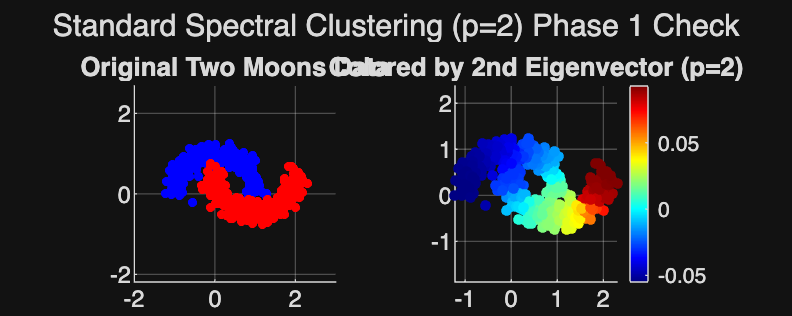


% eigs might not sort them perfectly, so let's ensure we get the smallest
eigenvalues = diag(D_eig);
[sorted_evals, idx] = sort(eigenvalues);
V = V(:, idx);

% The first eigenvector (index 1) is ~0 (constant vector)
% The second eigenvector (index 2) is the Fiedler vector we need
v2 = V(:, 2);

%% 4. PLOTTING
figure('Position', [100, 100, 1000, 400]);

% Plot 1: The Original Noisy Data
subplot(1, 2, 1);
gscatter(X(:,1), X(:,2), y, 'br', '.', 10, 'off');
title('Original Two Moons Data');
axis equal; grid on;

% Plot 2: Colored by Second Eigenvector
subplot(1, 2, 2);
scatter(X(:,1), X(:,2), 15, v2, 'filled'); % Color by v2 values
colormap(jet);
colorbar;
title('Colored by 2nd Eigenvector (p=2)');
axis equal; grid on;

sgtitle('Standard Spectral Clustering (p=2) Phase 1 Check');